clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

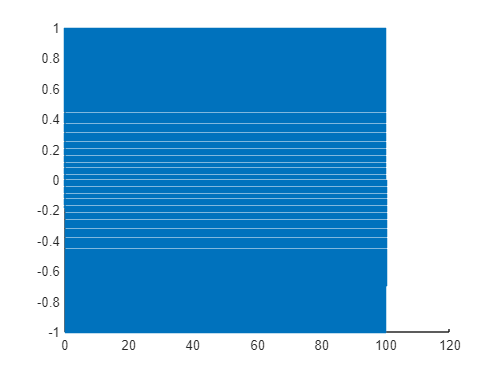

initial_0 = [1 0 0 0 0 0]';
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,0.0);
initial = ham_evolve(sigmax+sigmax^2,initial_0,pi/2);
%initial = initial_0;
a=0.0;
b=0.85;
timestep=0.001;timeend=100;
ham1 = +a*sigmax+1*sigmaz+b*sigmaz^2;
ham2 = 1*sigmax+1*sigmax^2;
timelist = ([0:timestep:timeend].*pi+0.1*sqrt(1+a^2)*pi)/sqrt(1+a^2*1);
for i = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(i));
    final_state(:,i) = ham_evolve(ham2,precess_state,pi/2);
    %final_state(:,i) = precess_state;
end
pop_state = abs(final_state).^2;

%plot(timelist,pop_state(1,:));
%ylim([0.5 1]);
%plot(timelist,pop_state(6,:));
%ylim([-0.1 0.3]);
sz(:)=(pop_state(1,:)-pop_state(6,:))./(pop_state(1,:)+pop_state(6,:));
scatter(timelist/pi,sz,'.');
ylim([-1 1]);

freq=fft(sz)

freq = 1.0e+04 *

   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i


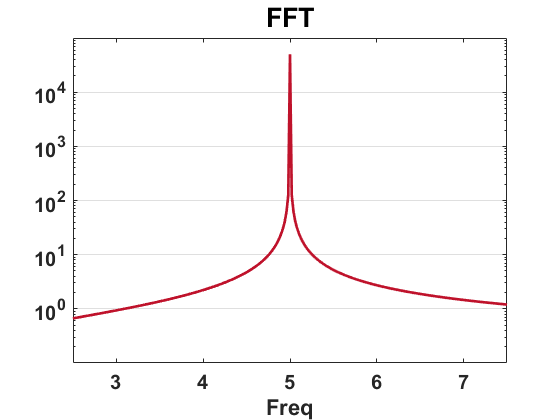

plot(1./timestep/length(timelist)*(0:(length(timelist)-1))*2,abs(freq),'LineWidth',2,"Color",'[0.75 0.07 0.17]')
set(gca,'FontSize',15,'FontName','arial','FontWeight','bold','YScale','log');
xlim([2.5 7.5]);
%xlim([0 30]);
ylim([10^-1 10^5])
xlabel('Freq');
title('FFT','FontSize',20,'FontName','arial','FontWeight','bold');
set(gcf,'visible','on');
set(gca,'YGrid','on','YTick',[1 10 100 1000 10000],'YMinorGrid','off');

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end